# **LAB SESSION 02**

## **Introduction to Bar Graph and Pie Charts.**

**Objective:** To get familiar with the Bar Graph and Pie Charts in MATLAB

**Introduction:**

    **Bar Graph/Diagram:**

    A bar graph/diagram is a graph that represents catagorical data with rectangular bars with heights or length proportional to the value that they represent. The bar can be ploted vertically or horizontally.

    There are three types of Bars;

- single

- grouped

- stacked

**    Syntax:**

- *Draw:*

- ` bar(y)   "It can `create a single bar graph with one bar for each element in `y`. If `y` is a matrix, then `bar` groups the bars according to the rows in `y`."

- ` bar(x,y) "It `draws the bars at the locations specified by `x`."

- ` bar(y,'type') or bar(x,y,'type') "It creates a bar graph of specific type. The two possible type inputs are 'grouped'(default) and 'stacked'.`

clc
clear all
close all
%Given Values of X and Y:
X = [1977,1999,2007,2015,2018]; %Name of Year
Y = [10,15,35,25,5];  %Recorded Value in Year
%NOTE: The Length of X and Y must be same.

Simple Bars:

bar(Y)

Bars at locations specified by X

bar(X,Y) %bar(x-axis,y-axis)

Special Cases with Bar-Graph

%Let Y-Initial Values are:
% 1)Unit Matrix
  Y1 = [2]; %Or simply a Scalar number e.g: 2
% 2)Row Matrix
  Y2 = [2,4,8,6];
% 3)Column Matrix
  Y3 = [2
        7
        3
        5]; %Also by Y3 = [2;7;3;5]
% 4)Full Matrix
%SQUARE
  Y41 = [2, 4, 8, 6
         7,16,22,20
         3,18,19,21
         5,25,15,10];
%RECTANGULAR
  Y42 = [2, 4, 8, 6
         7,16,22,20];
  Y43 = [2,2
         7,16
         3,18
         5,25];     

%Let X-Initial Values are:
% 1)Unit Matrix
  X1 = [1996]; %Or simply a Scalar number e.g: 1996
% 2)Row Matrix
  X2 = [1996,1997,1998,1999];
% 3)Column Matrix
  X3 = [1996
        2000
        3000
        4000]; %Also by Y3 = [9;8;4;5]
% 4)Full Matrix
%SQUARE
  X41 = [1996,1997,1998,1999
         2000,2001,2002,2003
         3000,3001,3002,3003
         4000,4001,4002,4003];
%RECTANGULAR
  X42 = [1996,1997,1998,1999
         2000,2001,2002,2003];
  X43 = [1996,1997
         2000,2001
         3000,3001
         4000,4001];

Plotting Y:

N = input('Name the Matrix you want to plot:\n " Y1 Y2 Y3 Y41 Y42 Y43 "\n');
bar(N)

Results:

1.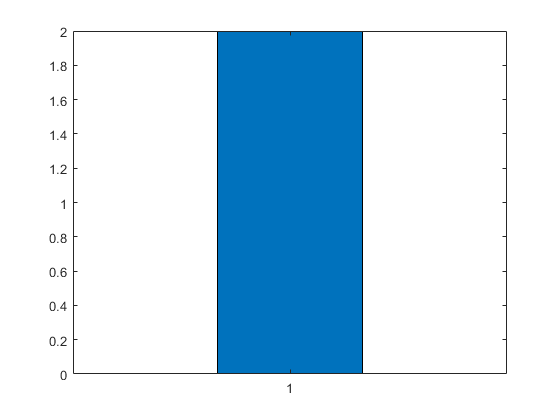

2.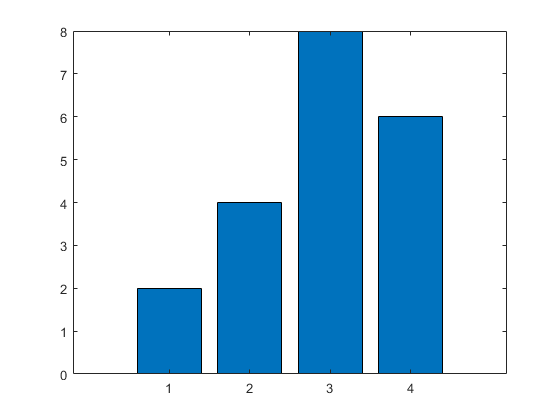

3.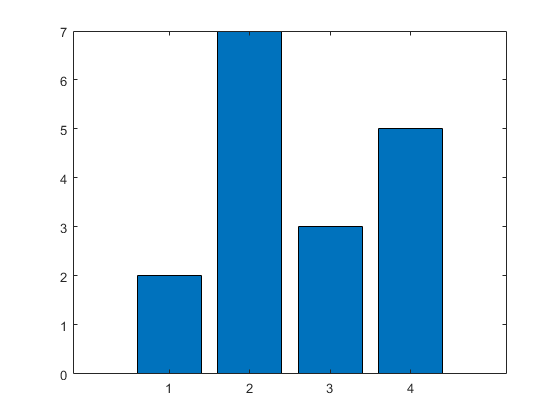

4.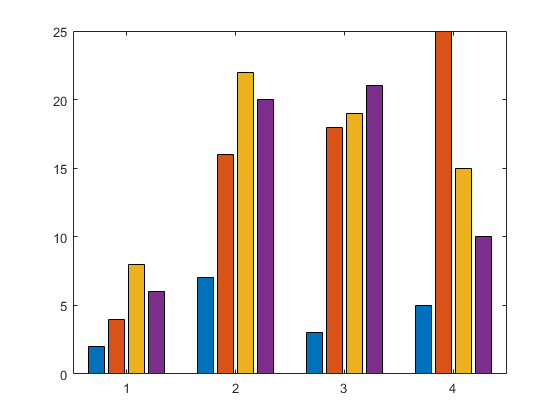

5.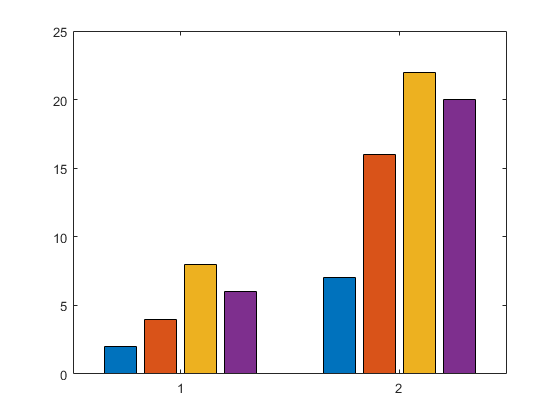

6.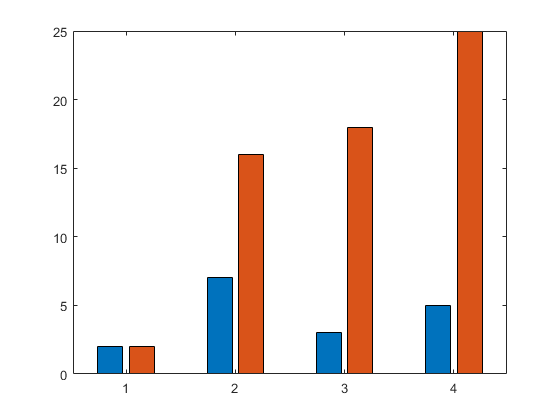

Plotting Y at specified X:

Nx = input('Name the Matrix you want to plot:\n " X1 X2 X3 X41 X42 X43 "\n');
Ny = input('Name the Matrix you want to plot:\n " Y1 Y2 Y3 Y41 Y42 Y43 "\n');
figure,
bar(Nx,Ny); %bar(x-axis,y-axis)

Results:

1.

2.

3.

4.

5.

6.

7.

8.

9.

10.

11.

12.

13.

14.

15.

16.

17.

18.

19.

20.

Specific Type Bar Graph

%Let Initial Values are:
B = [5,10,15; 10,20,30]; %y-axis
x = [1997,2018];         %x-axis

Grouped Bar Graph:

q = bar(x,B); %default is 'grouped' :)
% q = bar(x,B,'grouped')

Stacked Bar Graph:

P = bar(x,B,'stacked');

- *View Properties:*

- ` b = bar(``___``) "It `returns one or more `Bar` objects. If `y` is a vector, then `bar` creates one `Bar` object. If `y` is a matrix, then `bar` creates a `Bar` object for each column. Use`b` to make future modifications to the `Bar` objects after they are created."

*Properties stored in a Sacalar ***P***...*

P = bar(Y)  %Scalar Shows Properties
            %bar() plots the Bar-Graph

- *Properties Edit:*

- ` P.PropertyName "It edits the Specific property live on the bar graph.The operator P must be the sacalar onto which the bar is stored e.g: P=bar(__). The PropertyName must match those given by matlab e.g: BarWidth, the new value must match the data-tye and range allowed by that propert e.g: =1.5 or =[0 1 1].`

- `bar(``___``,width) "It `sets the relative bar width, which controls the separation of bars within a group. Specify `width` as a scalar value. Use this option with any of the input argument combinations in the previous syntaxes."

- ` bar(``___``,style) "It `specifies the style of the bar groups. For example, use `'stacked'` to display each group as one multicolored bar."

- ` bar(``___``,color) "It `sets the color for all the bars. For example, use `'r'` for red bars."

- ` bar(``___``,Name,Value) "It `modifies the bar chart using one or more name-value pair arguments. The settings apply to all bars plotted. For example, use`'EdgeColor','black'` to outline all the bars in black. The Name must correspond to those mentioned in Bar Properties and should be written in strings e.g: 'FaceColor'. The Value can be Scalar e.g: 1.5 or Vector e.g: [0 .5 .5] or something in strings e.g: 'black' ."

Access Bar Properties using Dot-Operator

% BarWidth: = scalar in range 0 to 1
P.BarWidth = 1;

A=[DATA] , X=[EXPLODE] and L={LABELS} must be the same Lengths


% LineWidth: = +ve value in point units. One point equals 1/72 inch
P.LineWidth = 1.5;

% BarLayout: = 'grouped'(default) or 'stacked'
P.BarLayout = 'grouped';

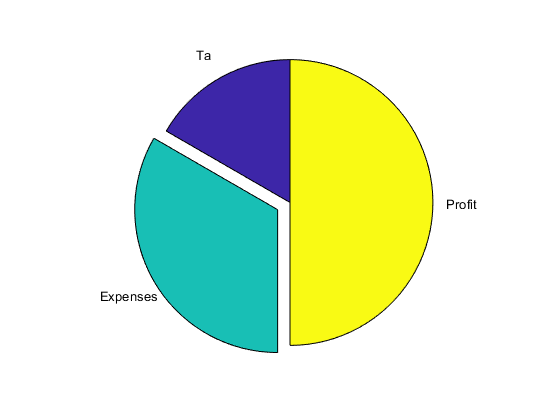

% Horizontal: = 'off'(default) or 'on'

P.Horizontal = 'on';

% FaceColor: = 'red' or 'r' or [1 0 0]
P.FaceColor = [0 .5 .5];

% EdgeColor: = 'red' or 'r' or [1 0 0]
P.EdgeColor = [0 .9 .9];

% XData: = vector
P.XData = [1977,1999,2007,2015,2018];
% YData: = vector
P.YData = [10,15,35,25,5];

Note: XData and YData must have equal lengths.

Edit Bar Property with Predefined values

% Bar Width:
bar(X,Y,0.8)

% Bar Color:
bar(X,Y,'r')

% Bar Name-Value pair arguments:
bar(X,Y,'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'LineWidth',1.5)

- *Naming:*

- ` text() "It gives name to a specific bar"`

bar(X,Y)
text(X,Y,'a')
text(X,Y,'abcdef')

%Unit Vector
text(X,Y,['a'])
text(X,Y,['abcdef'])  

%Row Vector
text(X,Y,['a','b','c','d','e'])
text(X,Y,num2str(Y))

%Column Vector
text(X,Y,['a';'b';'c';'d';'e'])
text(X,Y,num2str(Y'))

%Labels
L = {'a','b','c','d','e'}; %All alphabets must be Strings
L = {a;b;c;d;e}; % a,b,c,d,e must have some Scalar-value or Vector-value
                 % a=1 or a=[1,2] or a=[1;2]
L = {'1','2','3','4','5'}; %Scalars canbe both Strings or Digits
L = {1;2;3;4;5};

text(X,Y,{'a','b','c','d','e'})
text(X,Y,{1,2,3,4,5})
text(X,Y,L)

text(X,Y,{'a';'b';'c';'d';'e'})
text(X,Y,{1;2;3;4;5})
text(X,Y,L')

Results:

1.

2.

3.

4.

5.

%text(X,Y,num2str(A'))

%str = {'A','11','12','13','14'};
%text(X,A,str,'HorizontalAlignment','center','Vertic','bottom')
%text(X,A,str,'Position') ??


 **Pie Chart:**

    A pie chart is a circular satistical graphic which is divided into slices to illustrate numerical proportion. In a pie chart the arc-length of each slice is proportional to the quantity it represents.

    There are two types of Pie Charts;

- single

- grouped

%Syntax
pie(X)
pie(X,explode)
pie(X,labels)
pie(X,explode,labels)

`pie(`[`X`](#buiol_j-1-X)`)` draws a pie chart using the data in `X`. Each slice of the pie chart represents an element in `X`.

- If `sum(X) ≤ 1`, then the values in `X` directly specify the areas of the pie slices. `pie` draws only a partial pie if `sum(X) < 1`.

- If `sum(X) > 1`, then `pie` normalizes the values by `X/sum(X)` to determine the area of each slice of the pie.

- If `X` is of data type `categorical`, the slices correspond to categories. The area of each slice is the number of elements in the category divided by the number of elements in `X`.

`pie``(`[`X`](#buiol_j-1-X)`,`[`explode`](#buiol_j-1-explode)`)` offsets slices from the pie. `explode` is a vector or matrix of zeros and nonzeros that correspond to `X`. The `pie` function offsets slices for the nonzero elements only in `explode`.

If `X` is of data type `categorical`, then `explode` can be a vector of zeros and nonzeros corresponding to categories, or a cell array of the names of categories to offset.

`pie(`[`X`](#buiol_j-1-X)`,`[`labels`](#buiol_j-1-labels)`)` specifies text labels for the slices. `X` must be numeric. The number of labels must equal the number of elements in `X`.

`pie(`[`X`](#buiol_j-1-X)`,`[`explode`](#buiol_j-1-explode)`,`[`labels`](#buiol_j-1-labels)`)` offsets slices and specifies the text labels. `X` can be numeric or categorical. For numeric `X`, the number of labels must equal the number of elements in `X`. For categorical `X`, the number of labels must equal the number of categories.

`pie(X)`

%A = input('Enter the Event:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
A = [10 15 25 35 40];
pie(A)

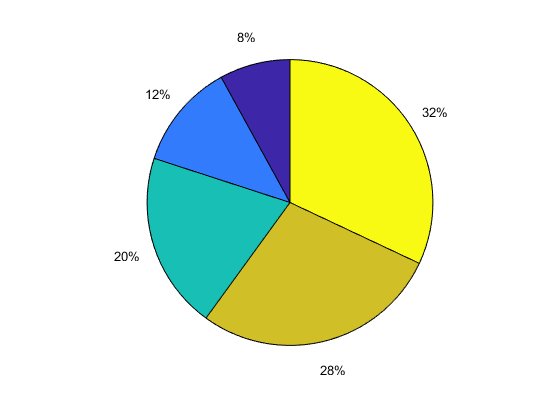

pie(X,explode)

disp('A=[DATA] and X=[EXPLODE] must be the same Lengths')
%A = input('Enter the Event:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
%X = input('Enter Exploding Values:\n 1 = Prominent\n 0 = Dominant     \n     1.Scalar (e.g: 1)\n<or> 2.Vector (e.g: [1,0,1])\n')
A = [10 15 25 35 40];
explode = [0 1 0 1 0]; % 1 = Prominent
                       % 0 = No Prominent
pie(A,explode)  % 'explode' can be any Logic Vector Variable like 'X'
                %  pie(A,X)           

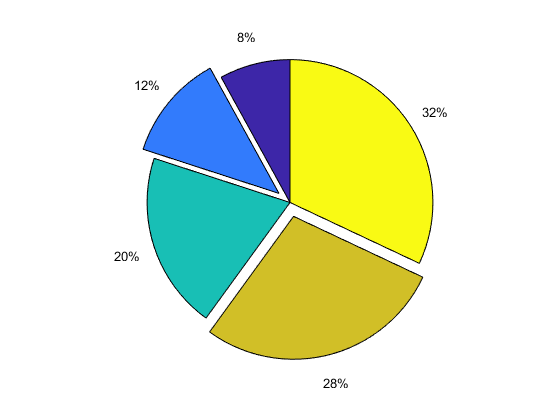

pie(X,labels)

disp('A=[DATA] and L={LABELS} must be the same Lengths')
%A = input('Enter the Event:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
%L = input('Enter Pie Labels:\n     1.Array (e.g: {"Ali","Awais","Hassan","Ashter"})\n')
A = [10 15 25 35 40];
labels = {'1997','2015','2017','2018','2020'};
pie(A,labels)   % 'labels' can be any Array Set like 'L'
                % pie(A,L)

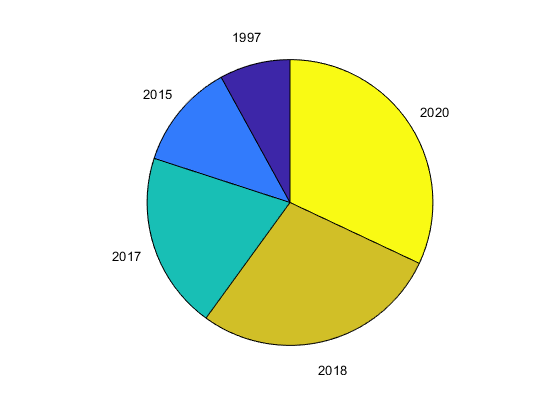

pie(X,explode,labels)

disp('A=[DATA] , X=[EXPLODE] and L={LABELS} must be the same Lengths')
%A = input('Enter the Event:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
%X = input('Enter Exploding Values:\n 1 = Prominent\n 0 = Dominant     \n     1.Scalar (e.g: 1)\n<or> 2.Vector (e.g: [1,0,1])\n')
%L = input('Enter Pie Labels:\n     1.Array (e.g: {"Ali","Awais","Hassan","Ashter"})\n')
A = [1 2 3];
X = [0 1 0]; % Explode Vector
L = {'Ta','Expenses','Profit'}; % Labels Vector
pie(A,X,L)